Our goal this time around is to isolate just hair cells. First, Load the image.

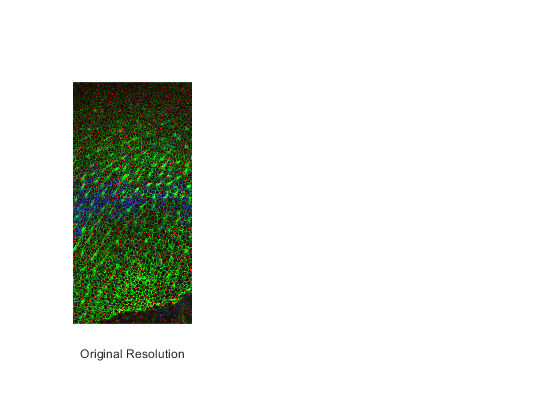

RAW = imread('../Data/Test Images/Illustrator Files/C57_WT_Utricle_1-01.png');

figure
subplot(1,3,1)
imshow(RAW)
xlabel('Original Resolution')

Again, we will downsample the image. 

For now we will use a downsampling scale of 1/20. Enough to speed up processing.

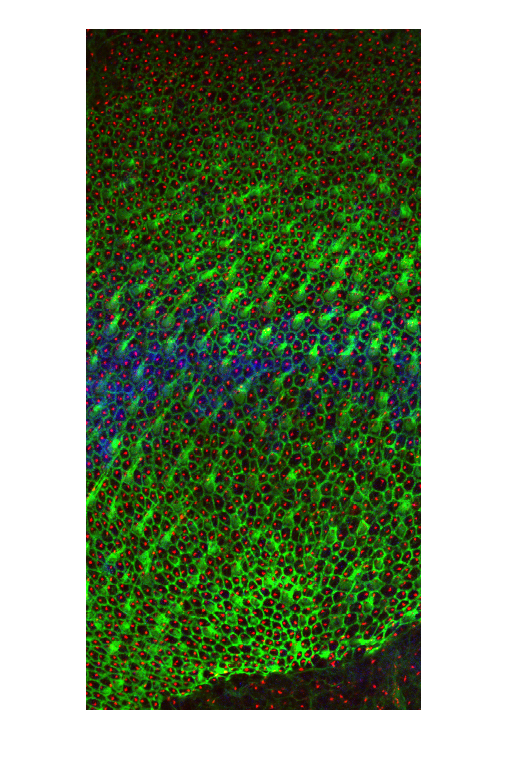


dRAW = imresize(RAW,0.05);

figure
imshow(dRAW)

Next we want to isolate each of the channels of the image.

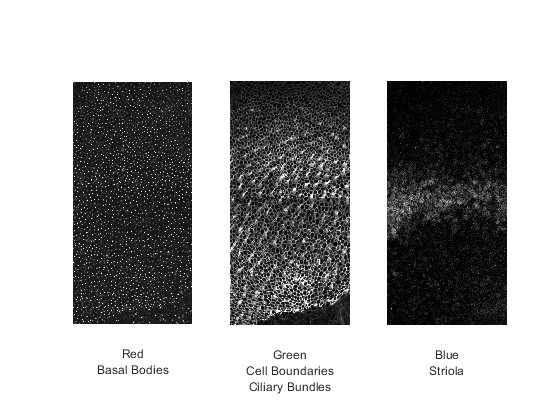

imR = dRAW(:,:,1);
imG = dRAW(:,:,2);
imB = dRAW(:,:,3);

figure
subplot(1,3,1)
imshow(imR)
xlabel({'Red','Basal Bodies'})

subplot(1,3,2)
imshow(imG)
xlabel({'Green','Cell Boundaries','Ciliary Bundles'})

subplot(1,3,3)
imshow(imB)
xlabel({'Blue','Striola'})

We will use the Green channel to identify hair cells as it clearly labels the hair cells cilia. 

Again we will level the image. 


diskRad = 100;
imBlur = imgaussfilt(imG,100);
imGEven = double(imG)./double(imBlur);
maxPix = max(imGEven(:));


Contrast the divided image. saturating the bottom 1% and the top 1% of all pixels values.

lowThresh = prctile(imGEven(:),1);
highThresh = prctile(imGEven(:),99);

imLevel = uint8(255*(imGEven-lowThresh)/(highThresh-lowThresh));

figure
imshow(imLevel)

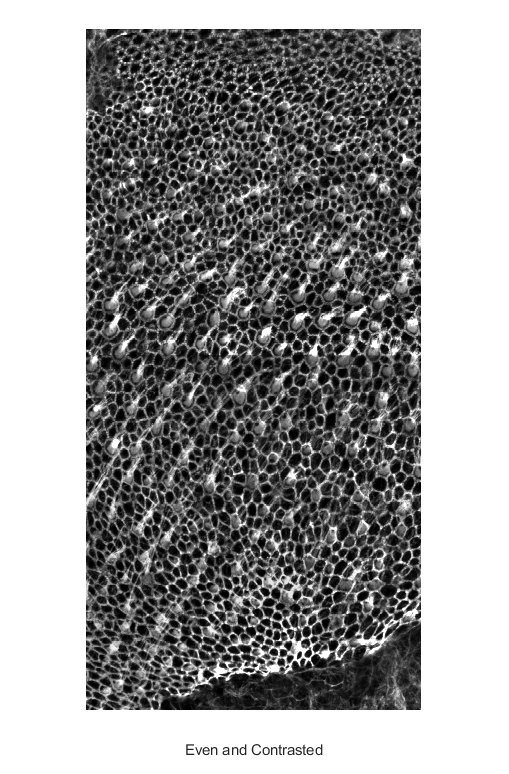

xlabel('Even and Contrasted')

Next we want to threshold the image to isolate primarily the pixels that represent the hair cells. Note that these pixels are neither the brightest nor the dimmest pixels in the image. 

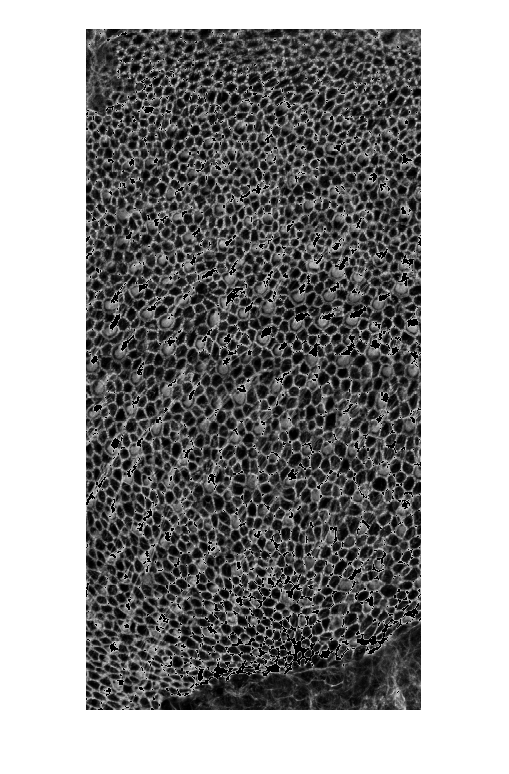

minIntensity = 0;
maxIntensity = 200;

imGAdj = imLevel;
imGAdj(imGAdj<minIntensity | imGAdj>maxIntensity) = 0;

figure
imshow(imGAdj)

Now Binarize to remove the cell boundaries, which are unfortunately the same color as the hair cells. 



imBW = imbinarize(imGAdj,'adaptive');

imCL = imclose(imBW,strel('disk',5));
imOP = imopen(imCL,strel('disk',8));
% imOP = imdilate(imOP,strel('disk',2));

figure
imshow(imBW)

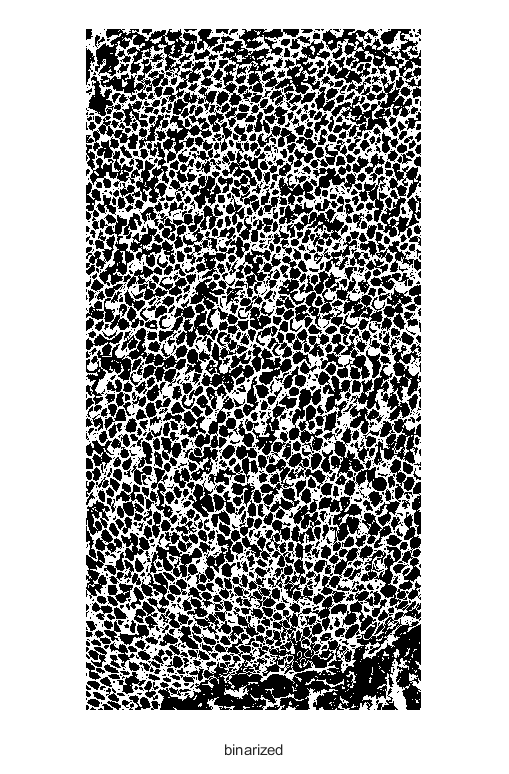

xlabel('binarized')

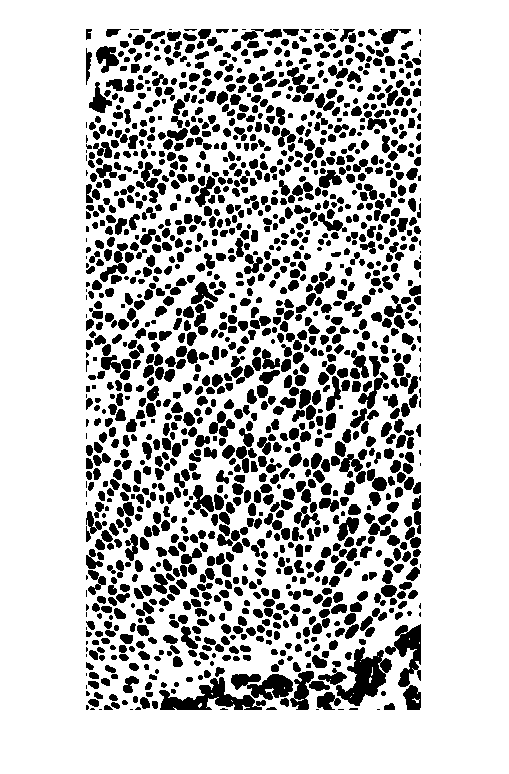

figure
imshow(imCL)


figure
imshow(imOP)

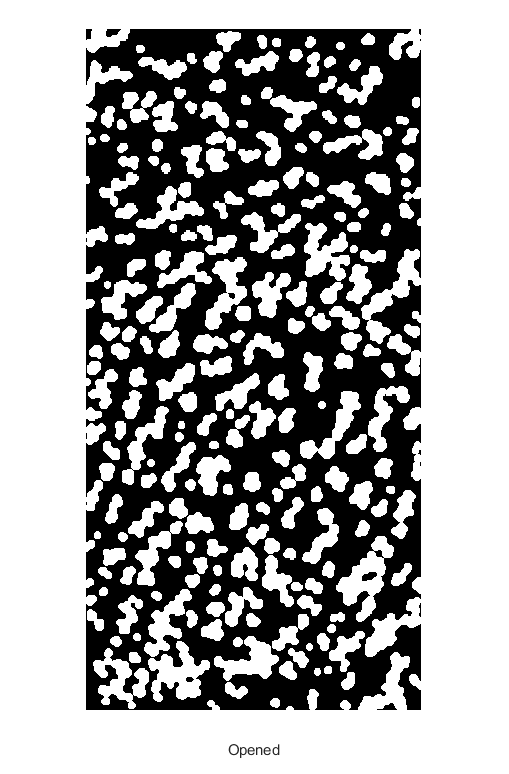

xlabel('Opened')

Now overlay the opened selection on the original image to see how we did. 

figure

figure
imshow(dRAW)

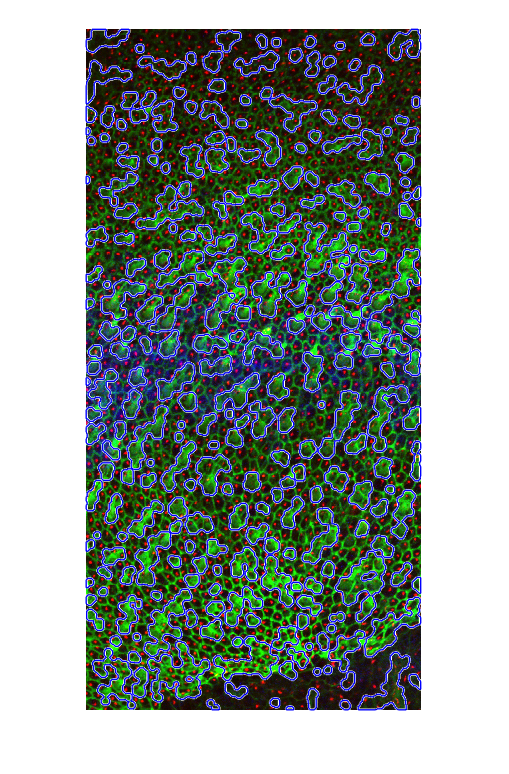

hold on
visboundaries(bwboundaries(imOP),'Color','b','LineWidth',1)

If we multiply this selection by the original leveled image we get the following. 

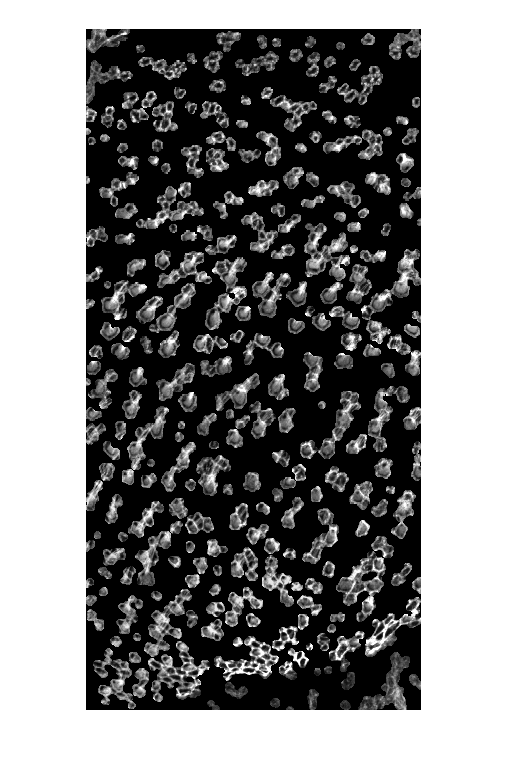

figure
imRef = uint8(double(imLevel).*double(imOP));
imshow(imRef)

Note we've selected all the hair cells and removed many support cells but also note that there are still support cells in the image. 

Let's go ahead and level it again

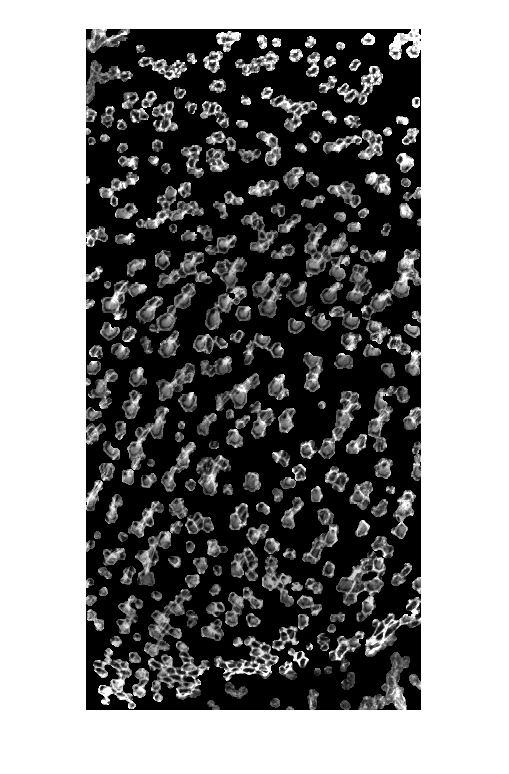

figure
imshow(CorrectIllumination(imRef))